clear; 
L1 = 4; L2 = 3; L3 = 2;
Theta0 = [10; 20; 30]*pi/180;
delta_t = 0.1;

% 每一步中的雅可比矩阵
J = myjacobian(Theta0, L1, L2, L3);
% 期望速度
V_c = [0.2;-0.3;-0.2];

% 期望力和力矩
W = [1; 2; 3];


% 每一步中的角度
Theta = Theta0;

% 存放角度
Angle = Theta0;
% 存放关节的角速度
Omega = [0;0;0];

% 机械臂模型
link1 = Link([0, 0, 0, 0], 'modified');
link2 = Link([0, 0, L1, 0], 'modified');
link3 = Link([0, 0, L2, 0], 'modified');
linkH = Link([0, 0, L3, 0], 'modified');
bot = SerialLink([link1 link2 link3 linkH], 'name', 'T0toH');
T = bot.fkine([Theta', 0]);

% 存放末端的位置和姿态
X = T.t; 
phi = Theta(1) + Theta(2) + Theta(3);

% 存放雅可比矩阵的行列式
J_det = [det(J)];

% 存放关节力矩
tao = [J'*W];

for t = 0+delta_t:delta_t:5
    J = myjacobian(Theta, L1, L2, L3);
    if det(J) == 0
        print("singular point\n");
        continue;
    else
        dTheta = inv(J)*V_c;
        Theta = Theta + dTheta*delta_t;
        Omega = [Omega, dTheta];
        Angle = [Angle, Theta];
        
        T = bot.fkine([Theta', 0]);
        X = [X, T.t];
        phi = [phi, Theta(1) + Theta(2) + Theta(3)];
        
        J_det = [J_det, det(J)];
        
        tao = [tao, J'*W];
    end
end


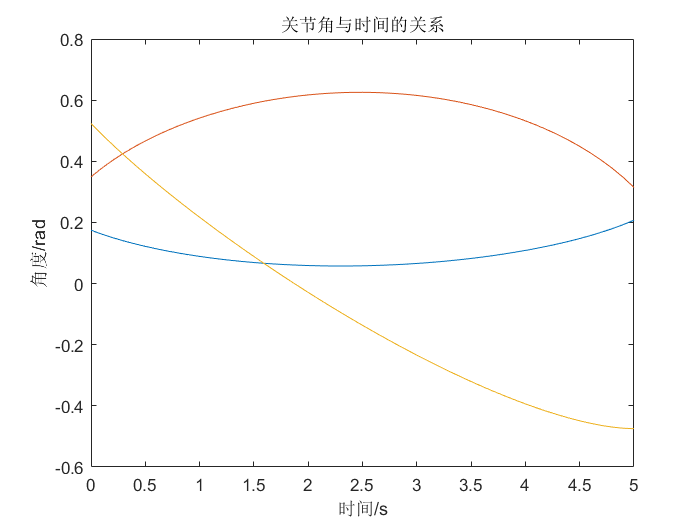

t = 0:delta_t:5;
plot(t, Angle)
title("关节角与时间的关系")
xlabel("时间/s"); ylabel("角度/rad")

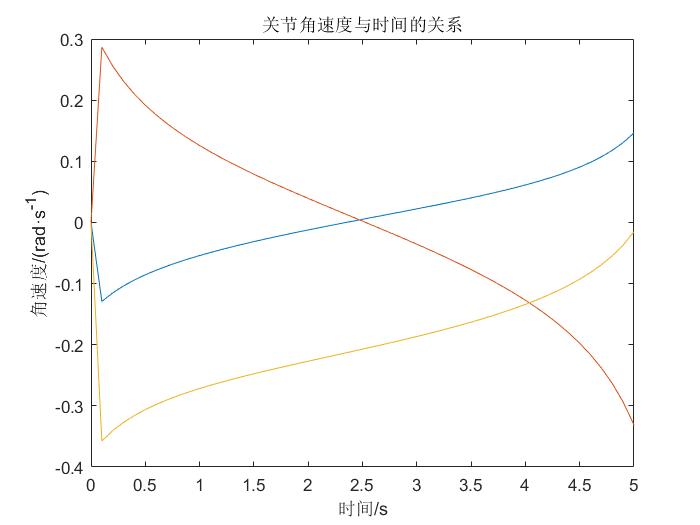

plot(t, Omega)
title("关节角速度与时间的关系")
xlabel("时间/s"); ylabel("角速度/(rad·s^{-1})")

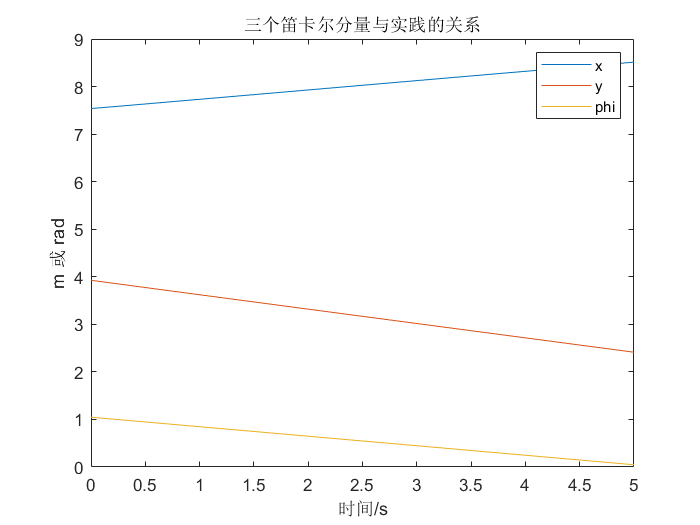

plot(t, [X(1:2, :); phi])
title("三个笛卡尔分量与实践的关系")
legend("x", "y", "phi")
xlabel("时间/s"); ylabel("m 或 rad")

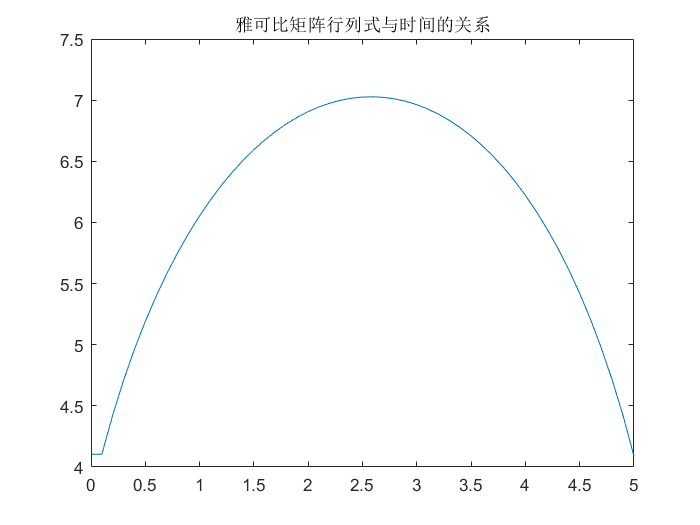

plot(t, J_det)
title("雅可比矩阵行列式与时间的关系")

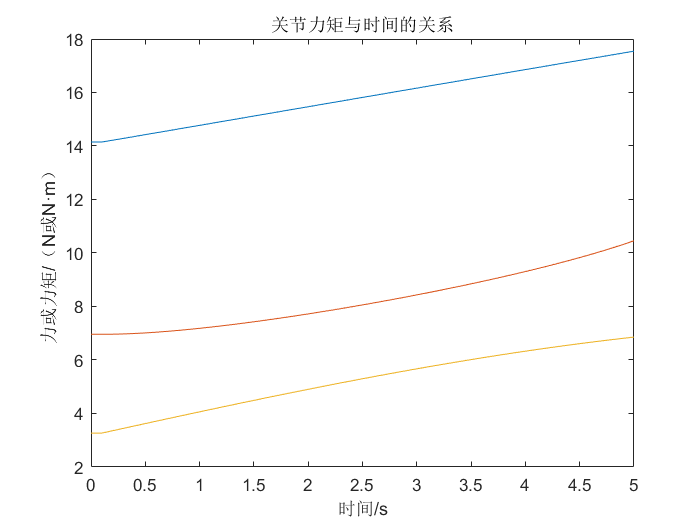

plot(t, tao)
title("关节力矩与时间的关系")
xlabel("时间/s"); ylabel("力或力矩/（N或N·m）")

使用工具箱验证雅可比矩阵

在起始位置

angle_0 = Angle(:, 1)

angle_0 =     0.1745
    0.3491
    0.5236


angle_end = Angle(:, end)

angle_end =     0.2074
    0.3145
   -0.4747


J_0 = bot.jacob0([angle_0' 0])

J_0 =    -3.9266   -3.2321   -1.7321         0
    7.5373    3.5981    1.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


myjacobian(angle_0, L1, L2, L3)

ans =    -3.9266   -3.2321   -1.7321
    7.5373    3.5981    1.0000
    1.0000    1.0000    1.0000


J_end = bot.jacob0([angle_end' 0])

J_end =    -2.4134   -1.5899   -0.0944         0
    8.5128    4.5984    1.9978         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


myjacobian(angle_end, L1, L2, L3)

ans =    -2.4134   -1.5899   -0.0944
    8.5128    4.5984    1.9978
    1.0000    1.0000    1.0000


可以看出，通过工具箱计算的雅可比矩阵和自己计算的结果相同（工具箱中计算出来结果比自己计算出来的多了一些用不到的行和列，关键部分是相同的）